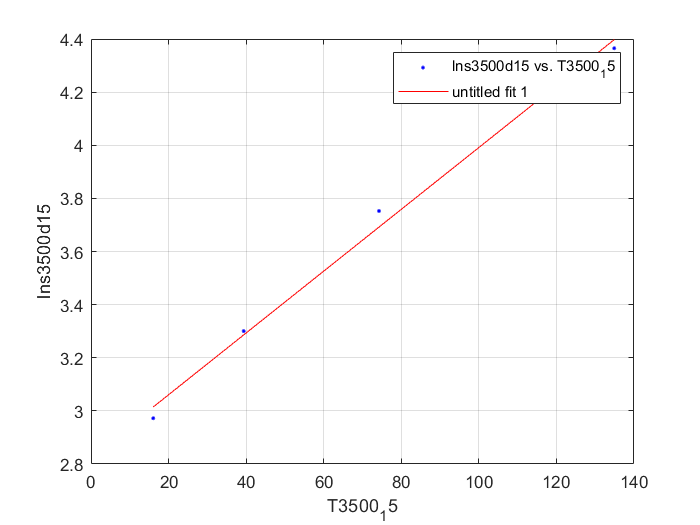

[xData, yData] = prepareCurveData( T3500_15, lns3500d15 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3500d15 vs. T3500_15', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T3500_15
ylabel lns3500d15
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01163  (0.008846, 0.01442)
  %     p2 =       2.828  (2.605, 3.051)

%Goodness of fit:
 % SSE: 0.006739
  %R-square: 0.9938
  %Adjusted R-square: 0.9907
  %RMSE: 0.05805